Aquí se aplica el gradiente conjugado para dos dimensiones. A continuación se establecen las condiciones iniciales. El valor c2 según la literatura se suele escoger como c2=0,1. Sin embargo, al hacer la simulación se ve que los pasos que se toman para este último valor son excesivos, por lo que se sigue utilizando c2=0,9.

clear
close all
hold off

%Vamos a representar cómo se mueve el centro de la formación

N=4; %Número de robots
iteration=500; %Número de iteraciones
D=1; %Radio de la formación
S=10^-4*[2,1;1,2]; %Matriz
c0=[20;20]; %Posición del centro inicial (initial guess)
r0=[0 0]'; %Centro de contaminación
e=[1;0];
w0=1; %Movimiento circular de un radián por segundo
k=1.01; %Valor para el line search inexacto

c1=10^-4;
c2=0.1; %Parámetros para el line search

colors=["ob","ok","or","om"];
tf=20;
t=linspace(0,tf,iteration);
%Condiciones iniciales
c(:,1)=c0;
plot(c0(1,1),c0(2,1),'ob')
hold on
r_c(:,1)=c(:,1)-r0;
mod_r_c(1)=norm(r_c(:,1));
mod_rc=mod_r_c(1);
pos_rob=zeros(2,N,iteration);
i=1;

Aquí se implementa el método:

while mod_rc>0.001

    if i==500
        break
    end
    grad_centr(:,i)=gradient_point2D(c(:,i),t(i),N,D,S,w0);
    pos_rob(:,1:N,i)=posicion_robots(c0,N,D,w0,i,t);
    if i==1
        p(:,i)=-grad_centr(:,i);
    end
    alpha1=1;
    steplengthParam=[c1,c2,alpha1,k];
    [alpha(i),u(i)]=alpha_strongWolfe(c(:,i), p(:,i), steplengthParam,t(i),N,D,S,w0);        
    c(:,i+1)=c(:,i)+alpha(i)*p(:,i);
    grad_centr(:,i+1)=gradient_point2D(c(:,i+1),t(i),N,D,S,w0);
    beta_k1=grad_centr(:,i+1)'*(grad_centr(:,i+1)-grad_centr(:,i))/(grad_centr(:,i)'*grad_centr(:,i));   %Polak-Ribiere   
    p(:,i+1)=-grad_centr(:,i+1)+beta_k1*p(:,i);
    %Hay un nuevo centro alrededor del cual se tienen que poner los robots
    c0=c(:,i);
    %Sacar el módulo de la diferencia entre el centro y el punto de
    %contaminación para cada iteración
    mod_r_c(i)=norm(c0-r0);
    %Para ver si va saltando el centro o es problema de la animación
 
    mod_rc=mod_r_c(i);
    i=i+1;
end
length(mod_r_c)

ans = 6

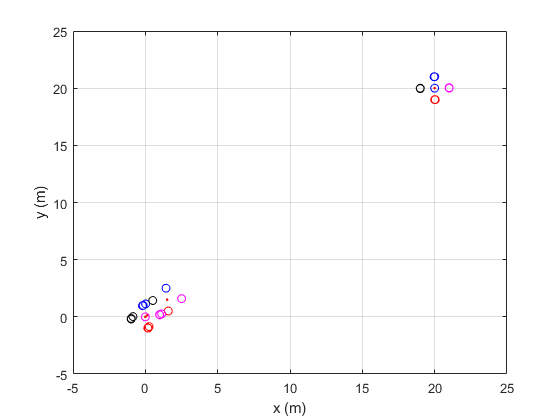

%Representación del centro
plot(c(1,:),c(2,:),'.r')
grid on
hold on
for g=1:N
    for z=1:iteration
        plot(pos_rob(1,g,z),pos_rob(2,g,z),colors(g))
        hold on
    end
end
xlabel('x (m)')
ylabel('y (m)')
hold off

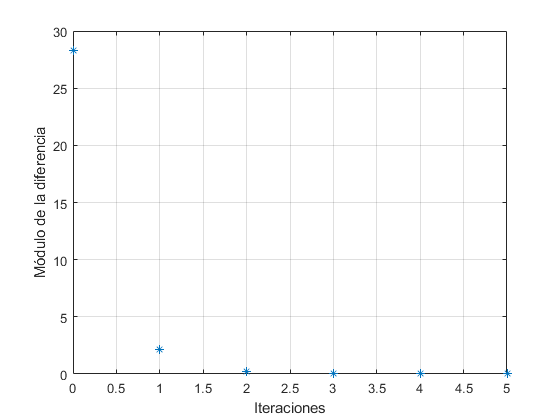

plot(0:length(mod_r_c)-1,mod_r_c,"*")
xlabel("Iteraciones")
ylabel("Módulo de la diferencia")
grid on

%error final para cada step-size
error=norm(c(:,length(mod_r_c))-r0)

error = 1.6538e-04

c0

c0 = 	1.0e+-3 *

    0.1168
    0.1170


Al variar las constantes c1 y c2 del "Strong Wolfe line search", el ritmo de convergencia varía drásticamente.